% [x, fs] = audioread("percepcja.wav");
% x = x / max(x);
% 
% lbls = label(x, fs);
% f0 = pitchwin(x, fs, round(fs * 0.1));
% f0(lbls ~= 2) = 0;
% 
% silence = x;
% silence(lbls ~= 0) = 0;
% 
% unvoiced = x;
% unvoiced(lbls ~= 1) = 0;
% 
% voiced = x;
% voiced(lbls ~= 2) = 0;
% 
% figure;
% hold on;
% plot(unvoiced);
% plot(voiced);
% plot(silence);
% ylim([-1, 1]);
% legend("unvoiced", "voiced", "silence");
% 
% figure;
% plot(f0);

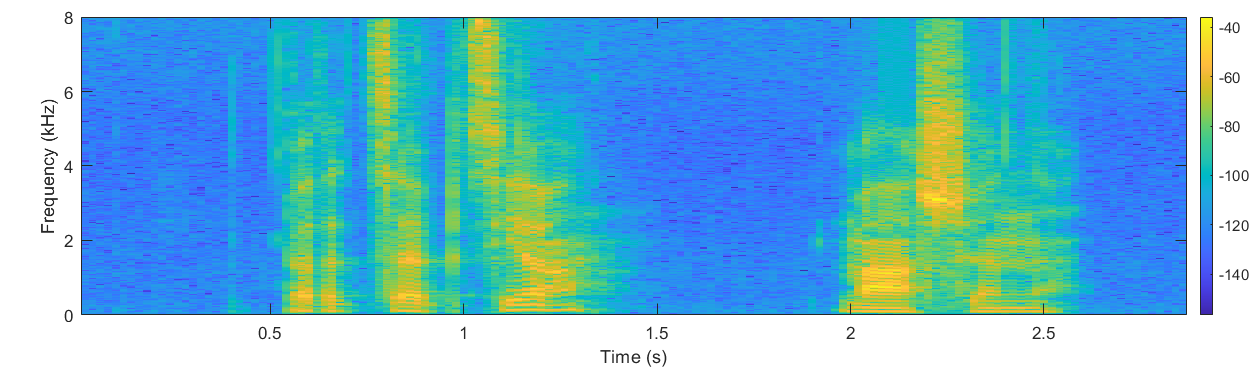

[x, fs] = audioread("percepcja.wav");
win = round(fs * 0.04);

figure("Position", [0 0 1000 300]);
tiledlayout(1,1,'TileSpacing','Compact','Padding','Compact');
nexttile;
spectrogram(x, win, win/2, [], fs, 'yaxis');

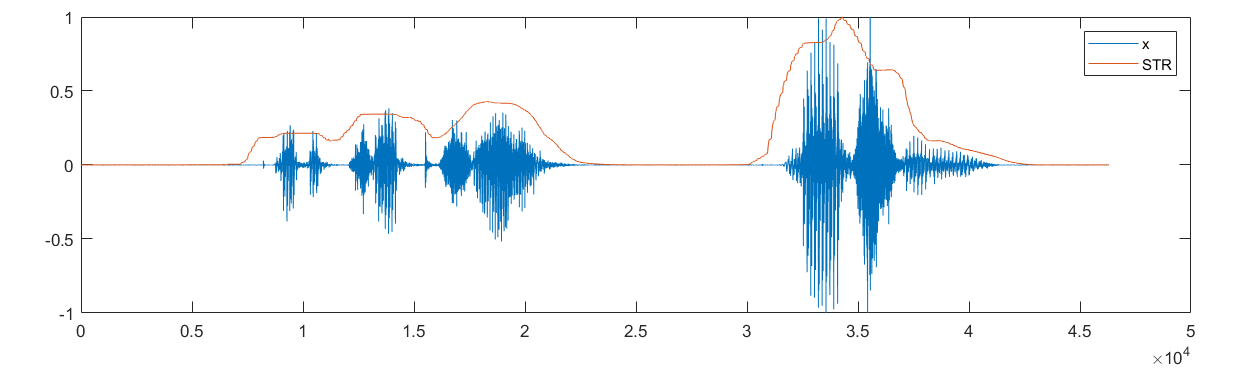

x = x - mean(x);
x = x / max(x);
figure("Position", [0 0 1000 300]);
tiledlayout(1,1,'TileSpacing','Compact','Padding','Compact');
nexttile;
plot(x);
ylim([-1 1]);
% długość okna analizy: 200 ms
win = round(fs * 0.2);
% energia chwilowa
ste = conv(x.^2, ones(1,win), 'same');
ste = ste / max(ste);
% wersja z pierwiastkiem
str = sqrt(ste);
hold on;
plot(str);
legend("x", "STR");

str_th = 0.015;
silence = [];
for i=1:length(x)
    if str(i) < str_th
        silence(end+1) = i;
    end
end

x1 = x;
x2 = [0; x(1:end-1)];
diff = sign(x1) ~= sign(x2);
zcr = conv(diff, ones(1, win) / win, "same");
for i=1:length(x)
    if ismember(i,silence)
        zcr(i) = 0;
    end
end
figure("Position", [0 0 1000 300]);
tiledlayout(1,1,'TileSpacing','Compact','Padding','Compact');
nexttile;
plot(x / max(x));
ylim([-1 1])
hold on;
plot(zcr);
hold on;
voiced_th = 0.29

voiced_th = 0.2900

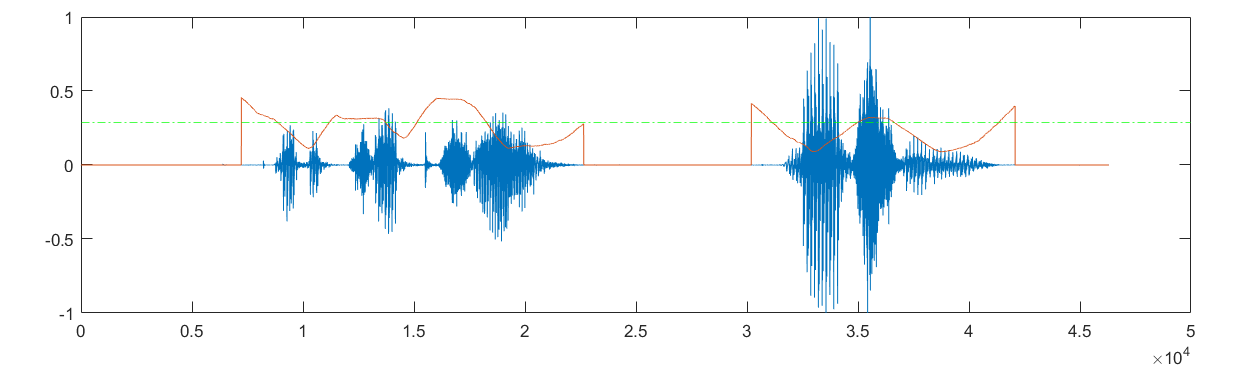

yline(voiced_th,'-.g')

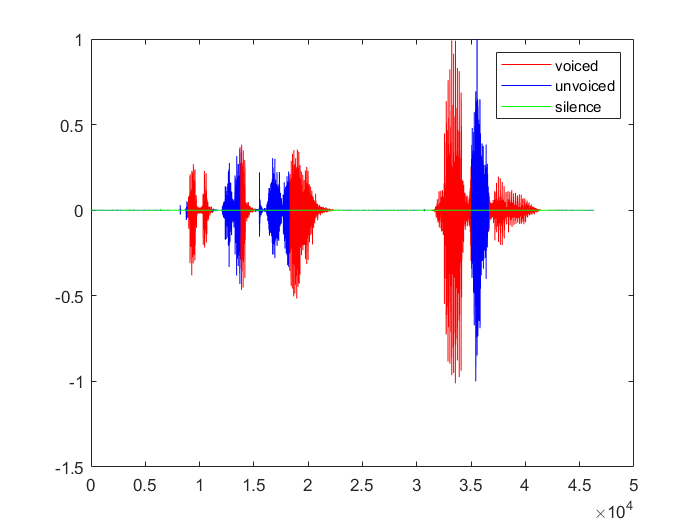

voiced = [];
unvoiced = [];
for i=1:length(x)
    if not(ismember(i,silence))
        if zcr(i) > voiced_th
            unvoiced(end+1) = i;
        else
            voiced(end+1) = i;            
        end
        
    end
end

silence_plot = [];
for i=1:length(x)
    if not(ismember(i,silence))
        silence_plot(end+1) = 0;
    else
        silence_plot(end+1) = x(i);
    end
end
silence_plot = silence_plot';

unvoiced_plot = [];
for i=1:length(x)
    if not(ismember(i,unvoiced))
        unvoiced_plot(end+1) = 0;
    else
        unvoiced_plot(end+1) = x(i);
    end
end
unvoiced_plot = unvoiced_plot';

voiced_plot = [];
for i=1:length(x)
    if not(ismember(i,voiced))
        voiced_plot(end+1) = 0;
    else
        voiced_plot(end+1) = x(i);
    end
end
voiced_plot = voiced_plot';



figure;
plot(voiced_plot,'r')
hold on;
plot(unvoiced_plot,'b')
plot(silence_plot,'g')
hold on;
legend("voiced","unvoiced", "silence");

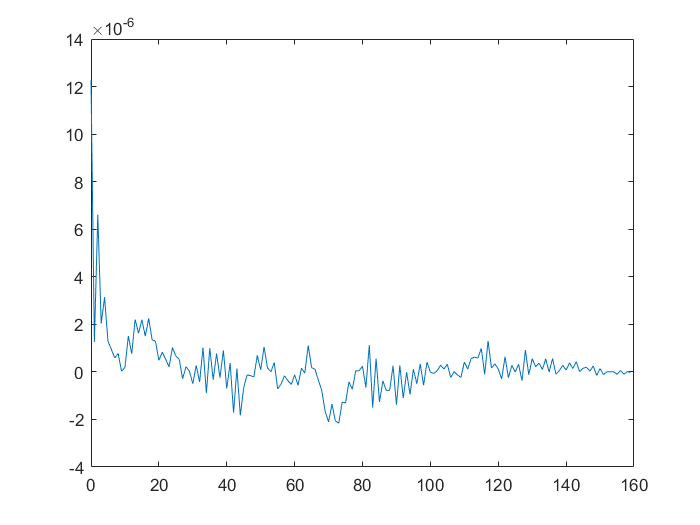


[r1, lags] = xcorr(x(1:160,1));
% wycięcie jedynie dodatnich przesunięć
r1 = r1(lags >= 0);
lags = lags(lags>=0);
figure;
plot(lags,r1)

% [pks, loc] = findpeaks(r1, "MinPeakDistance", 10, "MinPeakProminence", 20);
% % przesunięcie w sekundach
% lag_s = loc(1) * 1/fs;
% % częstotliwość bazowa
% freq = 1/lag_s
